# Interface02NEulerNRK2

Teste da função NEuler e NRK2 com exemplo da sebenta de AM2

Arménio Correia | armenioc@isec.pt

aula04T | 05/03/2024 »  aula05P | 14/03/2024

     t      Exata     Euler      RK2      erroEuler    erroRK2 
    ____    ______    ______    ______    _________    ________

       1         2         2         2          0             0
    1.25    10.933    7.5214    11.016      3.412      0.082579
     1.5    31.748    20.032     32.01     11.716       0.26203



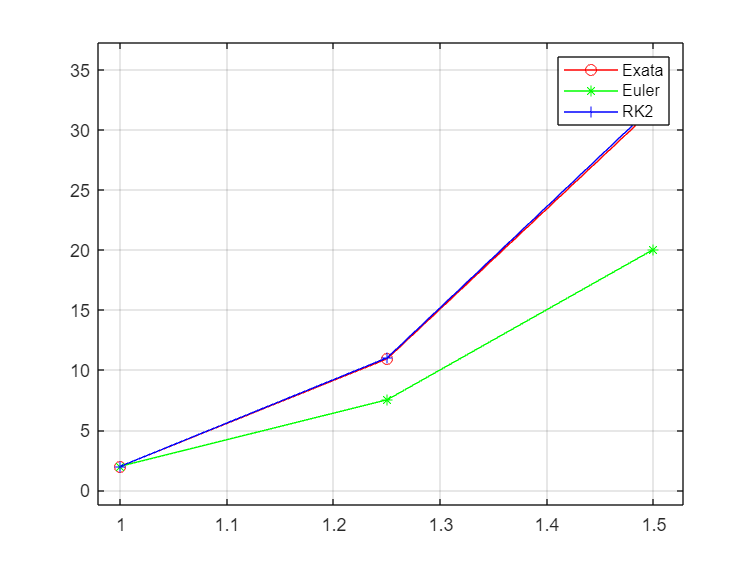

clear
syms y(t)

%% Dados do PVI 
% y'=f(t,y) t=[a,b] y(a)=y0

%help function_handle
strF = "y+exp(3*t)";
f =@(t,y) eval(vectorize(strF));
try
    fTeste = f(t,y);
    %f(0,1)
catch
    disp(upper("Introduza uma função em t e y"))
end
a = 1;
b = 1.5;
if ~(isscalar(b) && b>a)
    disp("Introduza um b > a")
end
n = 2;
y0 = 2;

try
    sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
    fplot(sExata,[a,b])
    %char(sExata)
    g =@(t) eval(vectorize(char(sExata)));
    
    [t,yEuler] = NEuler(f,a,b,n,y0);
    [~,yRK2] = NRK2(f,a,b,n,y0);
    
    yExata = g(t);
    erroEuler = abs(yExata-yEuler);
    erroRK2 = abs(yExata-yRK2);
    
    A = [t.',yExata.',yEuler.',yRK2.',erroEuler.',erroRK2.'];
    tabelaResultados = array2table(A,"VariableNames", ...
           ["t","Exata","Euler","RK2","erroEuler","erroRK2"]);
    disp(tabelaResultados)
    
    plot(t,yExata,"-ro")
    hold on
    plot(t,yEuler,"-g*")
    plot(t,yRK2,"-b+")
    hold off
    grid on
    legend("Exata","Euler","RK2")

catch Me
    %disp(upper("Ocorreu um erro na chamada das funções e/ou display de resultados"))
    %errordlg("Ocorreu um erro","ERRO","modal")
    errordlg(Me.message,"ERRO","modal")
end